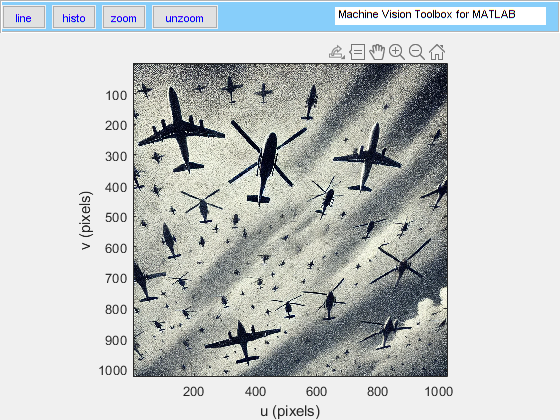

% Görüntüyü yükle
image = imread('uçak - helikopter.png');

% Görseli göster
idisp(image)

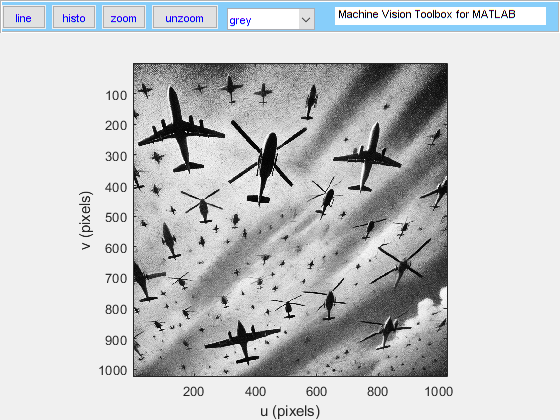


% Görüntüyü gri tonlamalıya çevir
grayImage = rgb2gray(image);

% irank fonksiyonnu çalışmadığı için medyan filtresi farklı şekilde
% oluşturarak tuz ve karabiber gürültüsünü giderme işlemi yapıldı

% Filtrelenmiş görüntü için bir matris oluştur
[m, n] = size(grayImage);
filteredImage = zeros(m, n);

% Filtre penceresi boyutu (3x3)
windowSize = 3;
halfWindow = floor(windowSize / 2);

% Medyan filtresini uygulama
for i = 1 + halfWindow : m - halfWindow
    for j = 1 + halfWindow : n - halfWindow
        % 3x3 komşuluk penceresini al
        neighborhood = grayImage(i - halfWindow:i + halfWindow, j - halfWindow:j + halfWindow);
        
        % Pencere içindeki piksellerin medyanını hesapla
        filteredImage(i, j) = median(neighborhood(:));
    end
end

% Filtrelenmiş görüntüyü uint8 türüne dönüştür
filteredImage = uint8(filteredImage);

% filtrelenmiş görüntüyü göster
idisp(filteredImage)


% filtrelenmiş görüntüyü bir eşik değeri belirleyerek 
% ikili hale çevirme işlemi
% Normalde eşik değer olarak 50 seçilmişti ancak nesne tanıma aşamasında
% iblob fonksiyonu çok fazla nesne bulduğu için RAM yetersiz kalıyordu
% bu nedenle daha az nesne belirgin olacak şekilde 
% 30 eşik değeri seçilmiştir
x = filteredImage >= 30

x = 1024×1024 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1

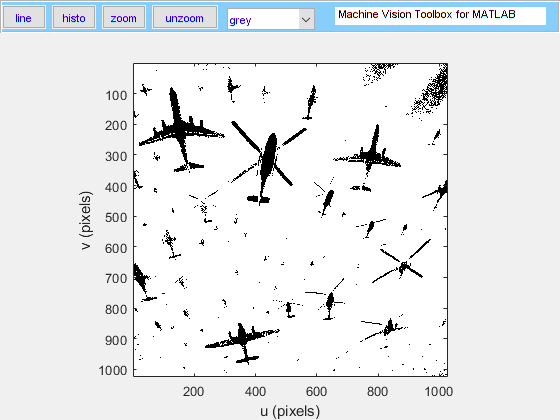


% İkili hale gelen siyah beyaz görseli göster
idisp(x)


% Görselin sınırlarını bulma işlemi
S = kcircle(3)

S =      0     0     0     1     0     0     0
     0     1     1     1     1     1     0
     0     1     1     1     1     1     0
     1     1     1     1     1     1     1
     0     1     1     1     1     1     0
     0     1     1     1     1     1     0
     0     0     0     1     0     0     0


closed = iclose(x, S)

closed =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1    

clean = iopen(closed, S)

clean =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     

opened = iopen(x, S)

opened =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     0     0     1     1     1     1     1     1     1     1     1     1     1     1    

closed = iclose(opened, S)

closed =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1    

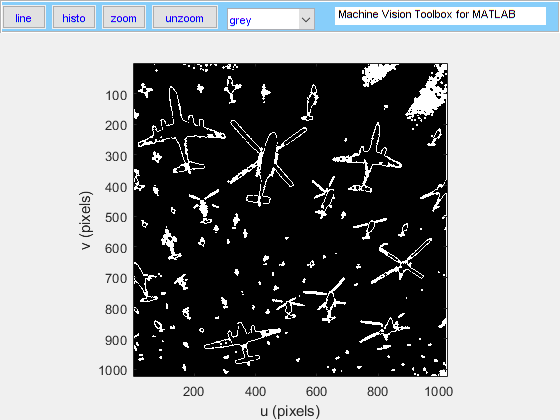



eroded = imorph(x, kcircle(3), 'min');

% Sınırları bulunmuş görseli göster
idisp(clean - eroded)


boundry = clean - eroded

boundry =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1   


% Görseldeki nesneleri tanımak için ilabel fonksiyonu kullanıldı

[label, m] = ilabel(boundry)

label =    315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315
   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315
   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315   315
   315   315   315   315   315   315   315   315   315   315   315   315   315   315   31

m = 316

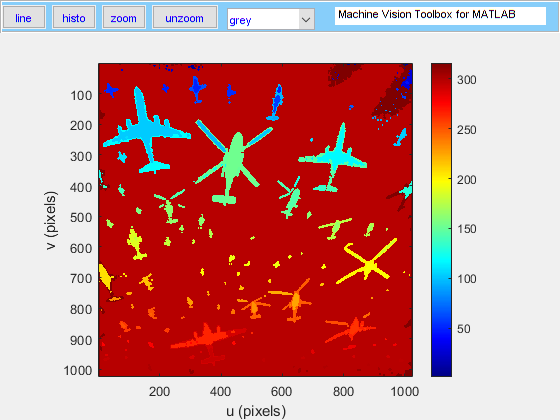


% Görselde objelerin renklendirilmiş ve arka plandan ayırılmış hali
idisp(label, 'colormap', jet, 'bar')


% Nesne tanıma aşaması
fv = iblobs(boundry, 'boundary', 'class', 1)

 
fv = 
 
(1) area=36, cent=(183.0,9.5), theta=1.57, b/a=0.922, class=1, label=6, touch=0, parent=298, perim=21.3, circ=1.108           
(2) area=146, cent=(309.0,14.0), theta=0.57, b/a=0.570, class=1, label=7, touch=1, parent=0, perim=6189.3, circ=0.000         
(3) area=36, cent=(223.5,11.0), theta=0.00, b/a=0.922, class=1, label=9, touch=0, parent=298, perim=21.3, circ=1.108          
(4) area=36, cent=(328.5,13.0), theta=0.00, b/a=0.922, class=1, label=11, touch=1, parent=0, perim=6189.3, circ=0.000         
(5) area=41, cent=(295.7,14.7), theta=-0.79, b/a=0.923, class=1, label=12, touch=0, parent=298, perim=22.7, circ=1.110        
(6) area=36, cent=(339.5,14.0), theta=0.00, b/a=0.922, class=1, label=13, touch=0, parent=298, perim=21.3, circ=1.108         
(7) area=29, cent=(200.0,16.0), theta=1.57, b/a=1.000, class=1, label=14, touch=0, parent=298, perim=19.3, circ=1.087         
(8) area=36, cent=(221.5,19.0), theta=0.00, b/a=0.922, class=1, label=17, touch=0, parent=298, perim=

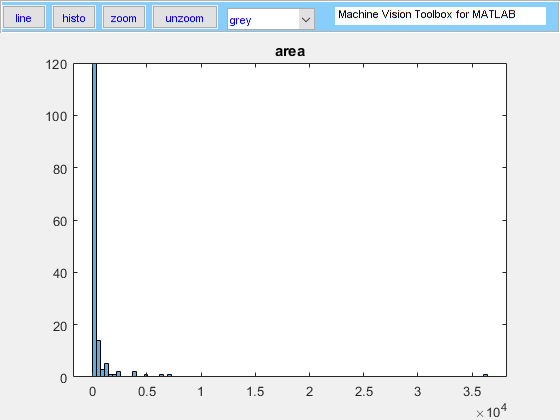


% Çıkarımlarda bulunmak için bazı parametrelerin histogram grafiği
% oluşturuldu
histogram(fv.area, 100)
title("area")

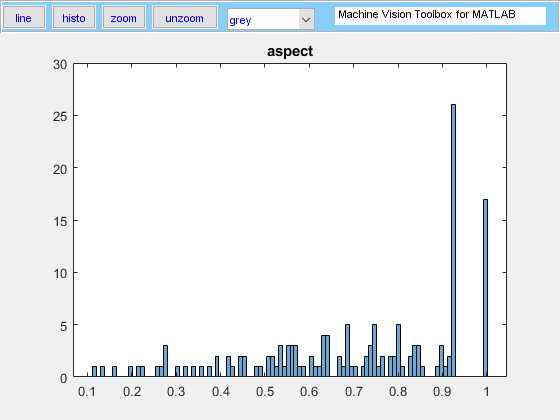

histogram(fv.aspect, 100)
title("aspect")

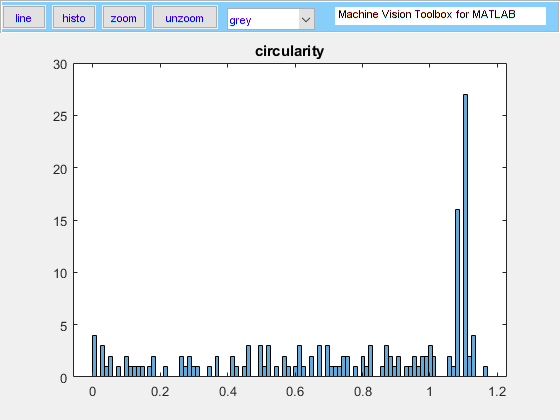

histogram(fv.circularity, 100)
title("circularity")

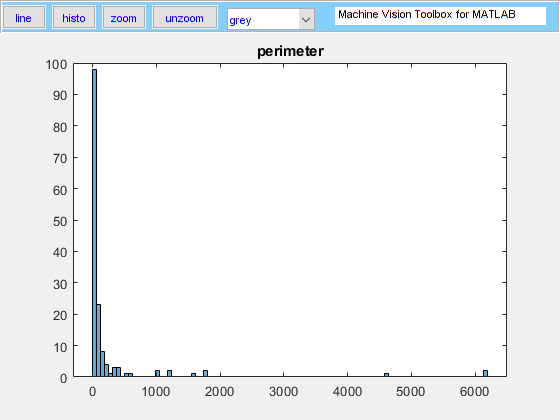

histogram(fv.perimeter, 100)
title("perimeter")

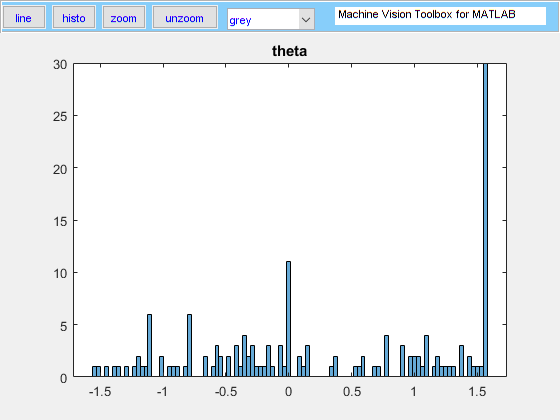

histogram(fv.theta, 100)
title("theta")

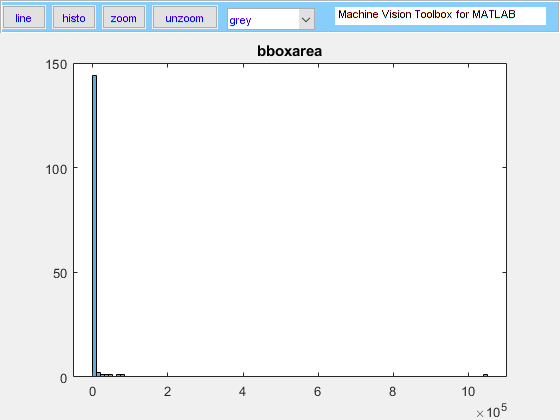

histogram(fv.bboxarea, 100)
title("bboxarea")

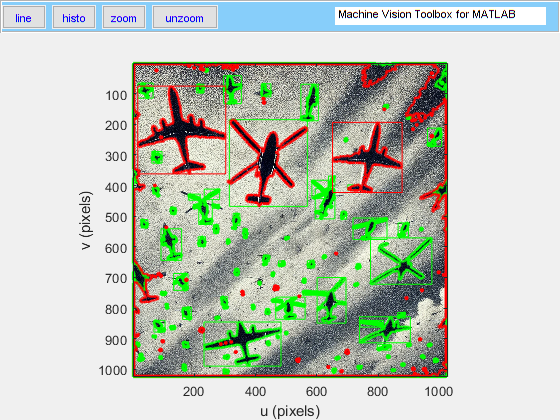


% Sınıflandırma için boş diziler oluştur
helicopters = [];
airplanes = [];

% aspect özelliğine göre nesnelerin sınıflarndırılmasına karar verildi.
% 0.83 katsayısı tekrar tekrar denenerek bulundu.
for k = 1:length(fv)
if fv(k).aspect > 0.83  
        airplanes = [airplanes; fv(k)];
    else  
        helicopters = [helicopters; fv(k)];
    end
end

% Görseli göster ve sınıflandırmayı çizdir
idisp(image);
hold on;

% Helikopterleri yeşil çerçeve ile çiz
for k = 1:length(helicopters)
    helicopters(k).plot_boundary('g', 'LineWidth', 2);
    helicopters(k).plot_box('g');
end

% Uçakları kırmızı çerçeve ile çiz
for k = 1:length(airplanes)
    airplanes(k).plot_boundary('r', 'LineWidth', 2);
    airplanes(k).plot_box('r');
end

hold off;


% Sınıflandırılmış nesne sayılarını yazdır
fprintf('Toplam Helikopter Sayısı: %d\n', length(helicopters));

Toplam Helikopter Sayısı: 95


fprintf('Toplam Uçak Sayısı: %d\n', length(airplanes));

Toplam Uçak Sayısı: 57
